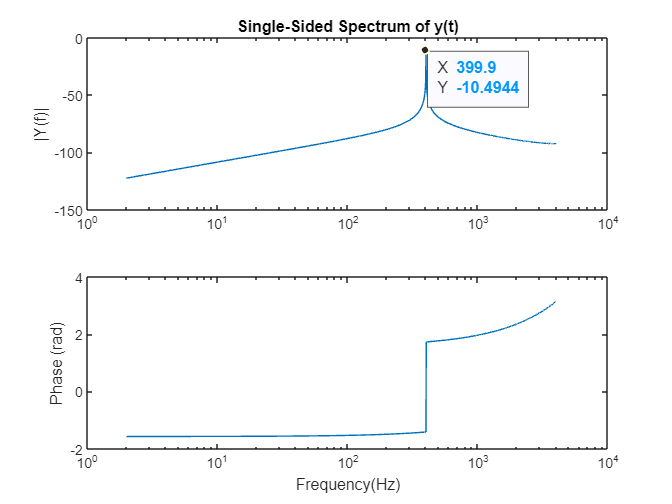

f0 = 2;
% Fs must be greater than 2*3000 as 3000hz is the max value we can see
fs = 8000;
[t signal] = generate_sinusoid(0.3,400,0,fs,0.5);
[y_spec freq] = make_spectrum(signal,fs);

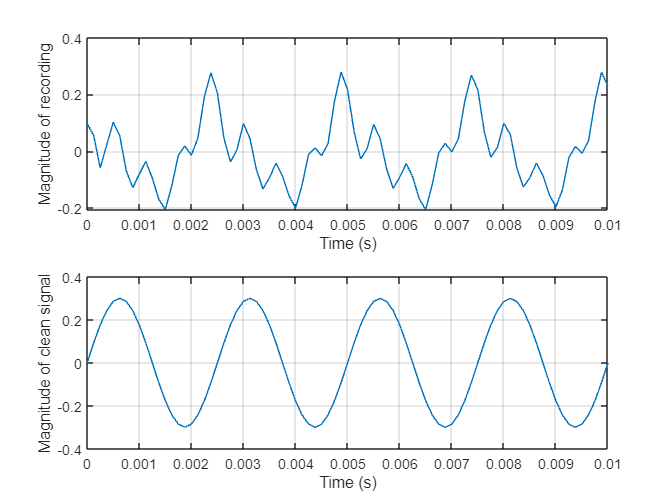

% Recording
[y,fs] = audioread(['C:\DTU\22051 DisSig\' '\' 'Final.wav']);
t2 = 0:1/fs:(length(y)-1)/fs;

% Plotting stuff
figure(2)
hold on
grid on
subplot(2,1,2)
plot(t,signal)
xlim([0,0.01])
xlabel('Time (s)')
ylabel('Magnitude of clean signal');
grid on
subplot(2,1,1)
plot(t2,y)
xlim([0,0.01])
grid on
xlabel('Time (s)')
ylabel('Magnitude of recording');
hold off

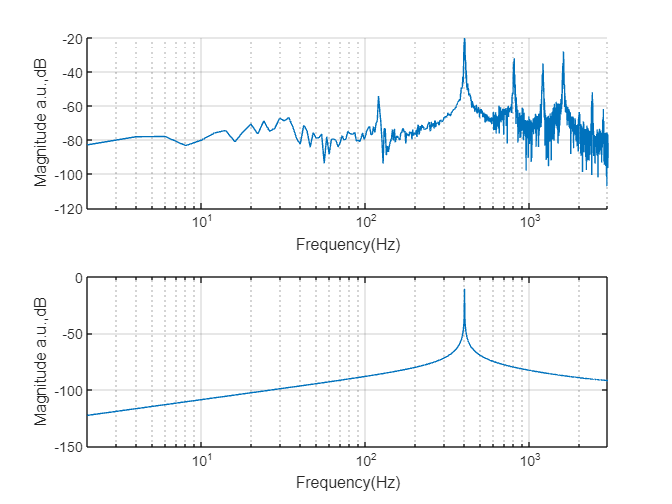

% Generation of spectrum
[y_rec freq_rec] = make_spectrum(y,fs);

%More Plotting
figure(3)
grid on
subplot(2,1,1)
set(gca(),'XScale','log')
hold on
semilogx(freq_rec,20*log10(abs(y_rec)))
ylabel('Magnitude a.u.,dB');
xlabel('Frequency(Hz)');
xlim([2,3000])
grid on
subplot(2,1,2)
set(gca(),'XScale','log')
semilogx(freq,20*log10(abs(y_spec)))
grid on
xlim([2,3000])
ylabel('Magnitude a.u.,dB');
xlabel('Frequency(Hz)');
hold off